Consider this Gazebo scene and associated visualization in RVIZ (i.e.  using a PointClouds2 visualizer, that then pulls in a  sensor_msgs/pointCloud2 message):

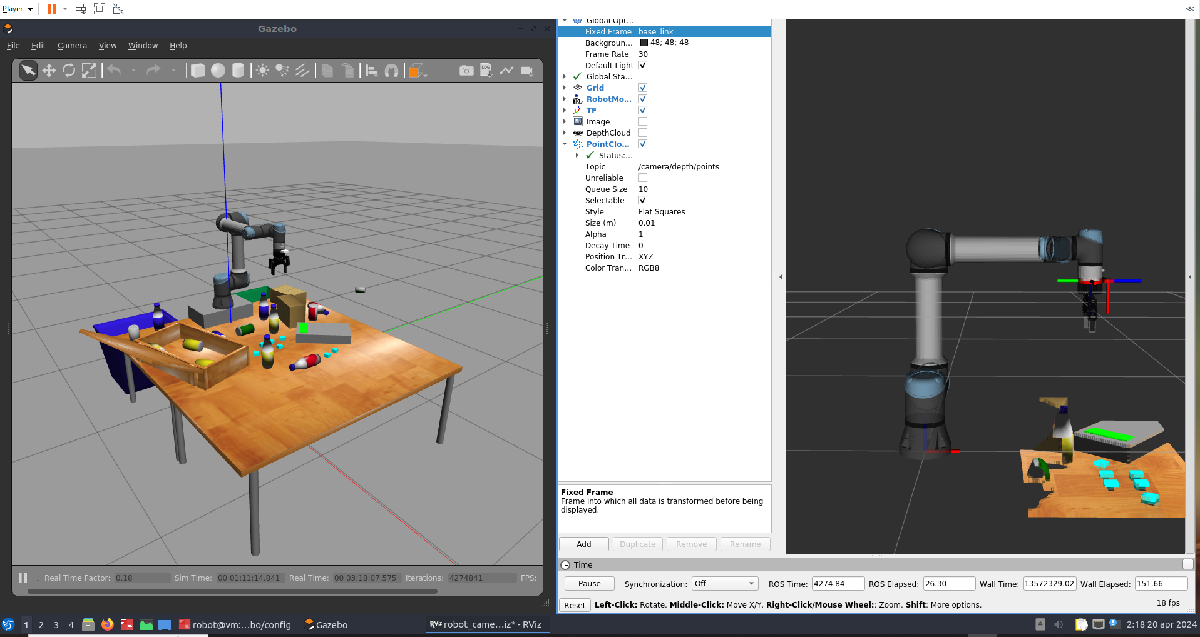

What is the reference frame in rviz here? base_link2 (by default it is world, but I am specifically working with base_link). 

What happens if I use camera_depth_link as the reference frame for rviz? Then you get this:

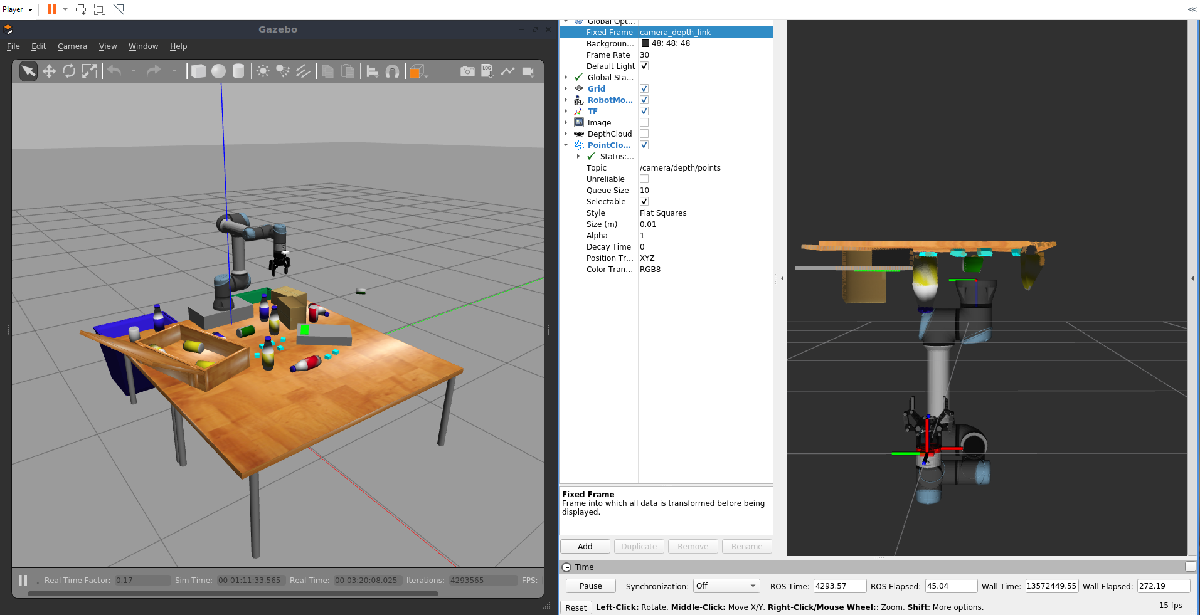

This is exactly what we get if we do a subscribe/receive call in Matlab on /camera/depth/image and then visualize it:

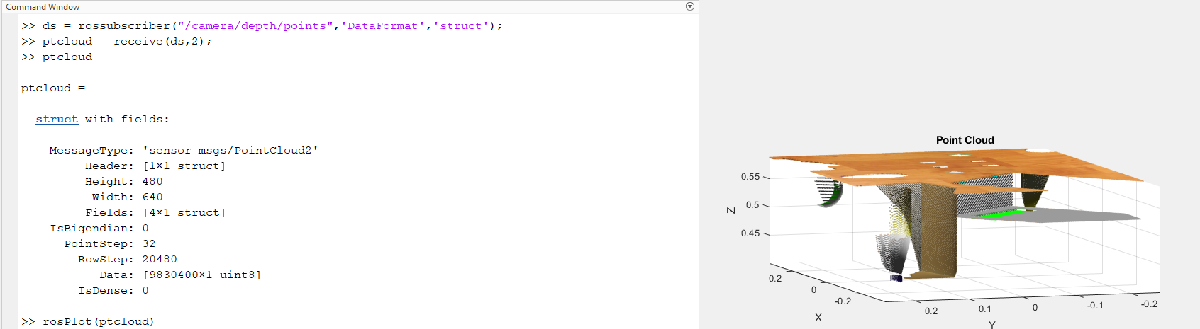

This is identical to what we have in the previous image. 

This means, we need to transform the XYZ points in the point cloud by  base_link_T_camera_depth_link to get the right projection. If you follow the code below, you will be able to obtain: 

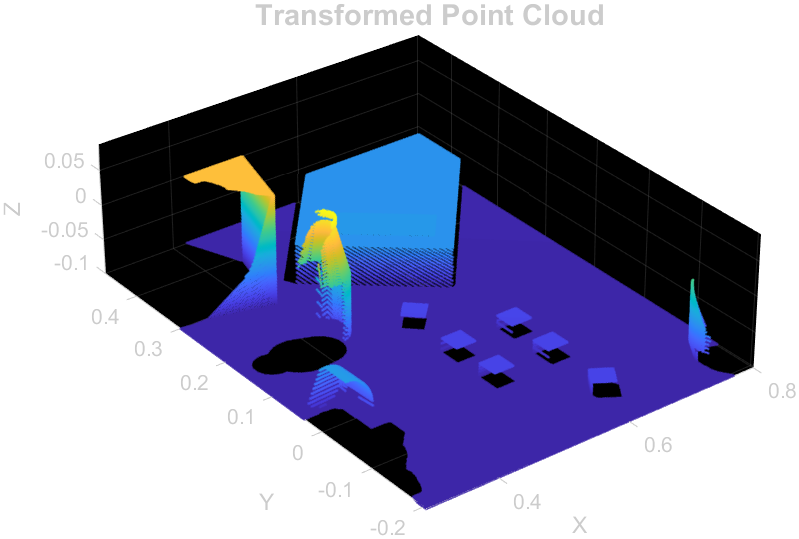

Get a pointcloud2 message:

ds = rossubscriber("/camera/depth/points",'DataFormat','struct');
ptcloud = receive(ds,2);

Get base_link to camera_depth_link transform

tftree       = rostf('DataFormat','struct');   

base         = 'base_link';
end_effector = ptcloud.Header.FrameId; %'camera_depth_link'; 

% Compute the ROS/Gazebo transform from base_link to camera_depth_link
waitForTransform(tftree, base,end_effector);
p = getTransform(tftree,base,end_effector,rostime('now'),'Timeout', tf_listening_time);

Get position and orientation and create a Homogeneous Transform

% Currently in ROS/Gazebo settings. No need to change anything.
pos = [ p.Transform.Translation.X, ... 
        p.Transform.Translation.Y, ...
        p.Transform.Translation.Z]; 
   
q = UnitQuaternion(p.Transform.Rotation.W, ...
                   [p.Transform.Rotation.X, ...
                    p.Transform.Rotation.Y, ...
                    p.Transform.Rotation.Z]);

Compute the 4x4

%Check q.T. 
q.T
T = transl(pos) * q.T;

Transform the pt cloud 

- Extract good xyz points

- Convert them into a homogeneous coordinate

- Transform all of the points by T

- Can invert order and multiply by T' to do this on all coordinates at the same time

- Remove the homogeneous coordinate 1 from transformed xyz points

- Recreate a point cloud 

% Extract Nx3 matrix of XYZ points
xyz = readXYZ(ptcloud);         

% Remove NaNs
%xyz = xyz(~isnan(xyz(:,1)),:);

% n rows by 3 cols with (x,y,z) tuples
[r,c]=size(xyz); 

% Transform each row of points, need homogeneous coords P=[x,y,z,1]'
pointsHomogeneous = [xyz, ones(size(xyz, 1), 1)];

% Apply the transformation
transformedPointsHomogeneous = pointsHomogeneous * T';

% Remove the homogeneous coordinate
transformedXYZ = transformedPointsHomogeneous(:, 1:3);

To visualize, use pcshow which expects a pointCloud type. We can take this xyz points and display after using pointCloud to instantiate a new object of this type.

% Recreate the pointCloud object if needed for visualization or further processing
% The pointCloud object creates point cloud data from a set of points in 3-D coordinate system. The points generally represent the x,y, and z geometric coordinates for samples on a surface or of an environment. Each point can also be represented with additional information, such as the RGB color. The point cloud data is stored as an object with the properties listed in Properties. Use Object Functions to retrieve, select, and remove desired points from the point cloud data.
transformedXYZPtCloud = pointCloud(transformedXYZ);

%% Visualize
figure2 = figure;
axes2 = axes(Parent=figure2);
pcshow(transformedXYZPtCloud,Parent=axes2,AxesVisibility='on');
xlabel('X');
ylabel('Y');
zlabel('Z');
title({'Transformed Point Cloud'},FontSize=14)

## Place back in Original Structure

We may need to place these transformed xyz points back into the original structure. To do this, we need to directly manipulating the raw data fields of the `PointCloud2` message. 

**Step 1: Analyze and Confirm Data Layout**

Before proceeding, confirm the exact byte layout of each point. The typical layout for `PointCloud2` with RGB might look like:

- X (float) - 4 bytes

- Y (float) - 4 bytes

- Z (float) - 4 bytes

- RGB (float or uint32) - 4 bytes

- Possible padding - 16 bytes (if needed, adjust based on your specific structure)

Start by getting number of points

numPoints = size(transformedXYZ, 1);

`Create a new data array of uint8 zeros`

newData = zeros(numPoints * ptcloud.PointStep, 1, 'uint8');

### Set XYZ and RGB info

You have to handle the data carefully to  ensure the integrity of the fields such as `PointStep`, `RowStep`, and the binary format of the `Data` array.

Assuming RGB is packed as a single `uint32`, where bytes are usually ordered as 0x00RRGGBB in memory:

for i = 1:numPoints
    % Each point's data starts at index base
    base = (i - 1) * ptcloud.PointStep + 1;
    
    % Convert each X, Y, Z to single precision, then convert to bytes (1x4 uint8) and place them in the correct position
    newData(base:base+3) = typecast(single(transformedXYZ(i, 1)), 'uint8');
    newData(base+4:base+7) = typecast(single(transformedXYZ(i, 2)), 'uint8');
    newData(base+8:base+11) = typecast(single(transformedXYZ(i, 3)), 'uint8');
    
    % Copy existing RGB data
    % Assuming RGB starts at byte 16 and is 4 bytes long
    rgbIndex = base + 16;
    newData(rgbIndex:rgbIndex+3) = ptcloud.Data(rgbIndex:rgbIndex+3);   
end

### `Update the original message's Data field`

ptcloud.Data = newData;